%%%% 

%%%%% in-class exercise, trajectory of unpowered projectile.

%%%%% find the luanch angle that would give the maximum landing range, and

%%%%% the corresponding landing range. 

v0 = 100;  %%% initial velocity
g = 9.8;  %%% gravity acceleration 
syms t theta

dx = v0*t*cos(theta)

$$dx = 100\,t\,\cos\left(\theta \right)$$

dy = v0*t*sin(theta) - 0.5*g*t^2

$$dy = 100\,t\,\sin\left(\theta \right)-\frac{49\,t^{2}}{10}$$


t_land = solve(dy,t)

$$t\_land = \left(\begin{array}{c} 0\\ \frac{1000\,\sin\left(\theta \right)}{49} \end{array}\right)$$

range = subs(dx,t,t_land(2))

$$range = \frac{100000\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{49}$$

theta_max = solve(diff(range))

$$theta\_max = \frac{\pi }{4}$$

max_range = double(subs(range,theta,theta_max))

max_range = 1.0204e+03

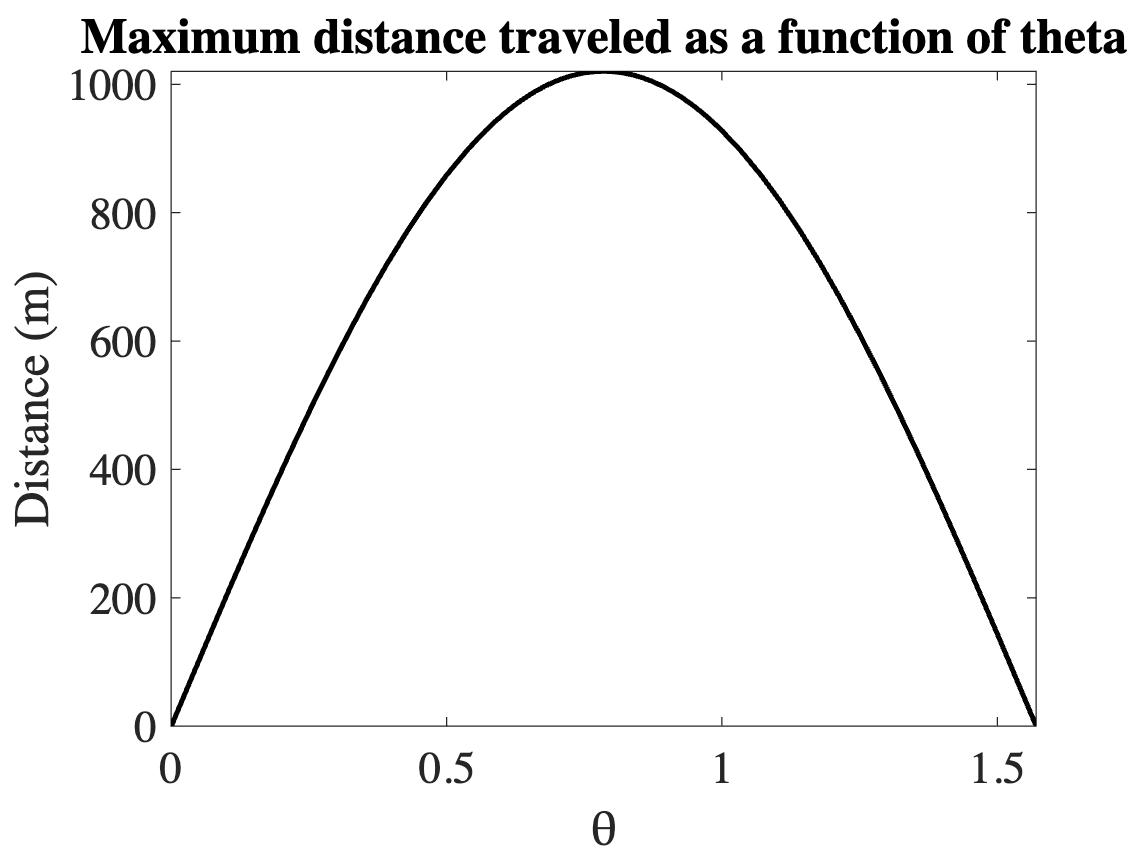

%%%% we can use fplot to plot symbolic function

fplot(range,[0,pi/2],'-k','LineWidth',2)
title('Maximum distance traveled as a function of theta')
xlabel('\theta')
ylabel('Distance (m)')
set(gca,'FontName','Times','FontSize',18)

%%%% max_range = vpa(subs(range,theta,theta_max),8)

syms x
y = x^2 - 2

$$y = x^{2}-2$$

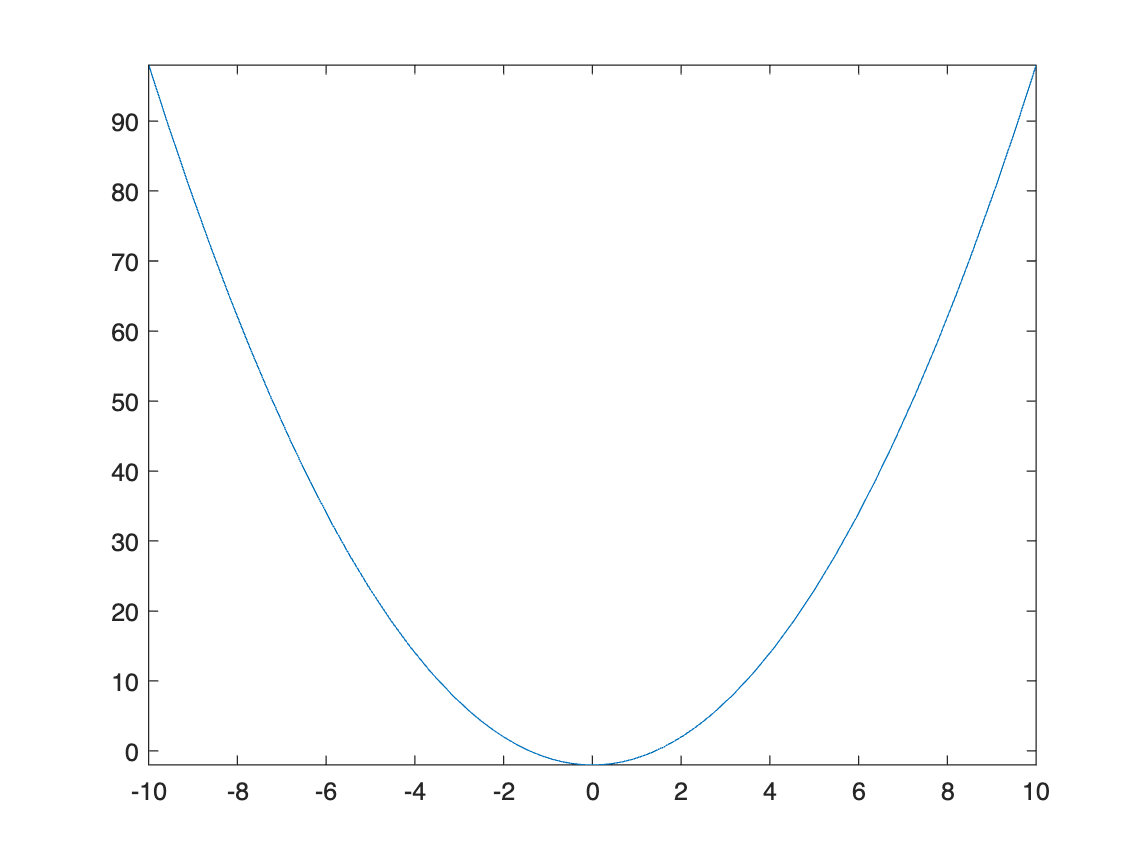

fplot(y,[-10 10])

fplot(x^2-2,[-10 10])


%%%% alternatively
theta_range = [0:0.01:pi/2];
%%% use symbolic plot to visualize range as a function of theta
range_numerical = double(subs(range,theta,theta_range))

range_numerical = 1.0e+03 *

         0    0.0204    0.0408    0.0612    0.0815    0.1019    0.1222    0.1424    0.1626    0.1827    0.2027    0.2227    0.2426    0.2623    0.2820    0.3016    0.3210    0.3403    0.3595    0.3785    0.3974    0.4161    0.4346    0.4530    0.4712    0.4892    0.5070    0.5246    0.5420    0.5592    0.5762    0.5929    0.6094    0.6256    0.6416    0.6574    0.6728    0.6880    0.7030    0.7176    0.7320    0.7461    0.7598    0.7733    0.7865    0.7993    0.8118    0.8240    0.8359    0.8474


[val,loc] = max(range_numerical);
theta_range(loc)

ans = 0.7900

An anonymous function is like an inline function in traditional programming languages, defined within a single MATLAB statement. It consists of a single MATLAB expression and any number of input and output arguments.

You can define an anonymous function right at the MATLAB command line or within a function or script.

This way you can create simple functions without having to create a file for them.

%%%% Anonymous function 
%%%% syntax: f = @(arglist)expression
%%%% example

power_cal = @(a,b) a^b

power_cal = function_handle with value:
    @(a,b)a^b


power_cal(3,2)

ans = 9


polynomial = @(a,b,c) a*b^2 + b*c + c

polynomial = function_handle with value:
    @(a,b,c)a*b^2+b*c+c


polynomial(power_cal(3,2),2,3)

ans = 45

introduce customized function.

[https://www.mathworks.com/help/matlab/ref/function.html](https://www.mathworks.com/help/matlab/ref/function.html)

syntax 

function [y1,...,yN] = myfun(x1,...,xM)

You can save your function:

- In a function file which contains only function definitions. The name of the file must match the name of the first function in the file.

- In a script file which contains commands and function definitions. Functions must be at the end of the file. Script files cannot have the same name as a function in the file. Functions are supported in scripts in R2016b or later.

%%% Function is a script that you can call from the another script

%%% single output.
x = 1:10

x =      1     2     3     4     5     6     7     8     9    10


ave = myAve(x)

ave = 5.5000



%%% multiple outputs

%%% calculate the mean and standard deviation

%%%% example
values = [12.7, 45.4, 98.9, 26.6, 53.1];
[ave,stdev] = stat(values)

ave = 47.3400

stdev = 29.4124




%%%% call function using handle @
% Compute the value of a sine function at 2*pi/3.

x = 2*pi/3;
y = myIntegrand(x)

y = 0.6495



%%%% function handle is needed when passing one function to another
%%%% function such as integral, fzero. syntax is f = @myfunction

xmin = 0;
xmax = pi;
f = @myIntegrand;
a = integral(f,xmin,xmax) %%%% the first element needs to be a function handle

a = 1.3333


%%%% for multiple inputs in the function, we use f=@(x) myfun(x,b)
b = 2;
f2 = @(x) myIntegrand2(x,b);
m = integral(f2,xmin,xmax) 

m = 4.4749




%%%% we can also pass an array to a function. 

a = 1;
b = 2;
c = 3;
ax = [1 2 3];
ay = [4 2 1];

for ij = 1:3
    ax(ij)^2*a+ay(ij)^2*b+c
end

ans = 36

ans = 15

ans = 14


output = poly(ax,ay,a,b,c)

output =     36    15    14



poly(ax,ay,a,b,c)

ans =     36    15    14



%%%% Example: use Newton's method to solve for the roots of f(x) = x^2 -3x + 2

%%%% x(k+1) = x(k) - f(x(k))/f'(x(k))

tolerance = 10^-12;
x = 0.5;
f = getf(x);
iter = 0;
iterM = 20;

while abs(f) > tolerance || iter < iterM
    df = getdf(x);
    x = x - f/df;
    f = getf(x);
    iter = iter+1;
end

x

x = 1

getf(x)

ans = 0



%%% we can also make the entire thing as a function 

% % % tolerance = 10^-12;
% % % x0 = 0.5;
% % % 
% % % [root,fvalue] = getroot(x0,tolerance)


% % % function [x,f] = getroot(x,tolerance)
% % % 
% % % 
% % % f = getf(x);
% % % iter = 0;
% % % iterM = 20;
% % % 
% % % while abs(f) > tolerance || iter < iterM
% % %     df = getdf(x);
% % %     x = x - f/df;
% % %     f = getf(x);
% % %     iter = iter+1;
% % % end
% % % 
% % % end




%%%% Example: Euler's method for IVP ODE.
%%% Example: find y(t) at t = 0.1, 0.2, and 0.3, with h = 0.1 
%%% for y' + 2y = 2 - e^(-4t); initial value y(0) = 1;

y_old = 1;
t = 0;
h = 0.1;
y = zeros(10,1);
time = zeros(10,1);

for i = 1:10
    y_new = y_old + h*getEulerf(y_old,t);
    t = t+h;
    y_old = y_new;
    y(i) = y_new;
    time(i) = t;
end
y

y =     0.9000
    0.8530
    0.8374
    0.8398
    0.8517
    0.8678
    0.8852
    0.9021
    0.9176
    0.9313


time

time =     0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000
    1.0000




%%% we can also make the entire thing as a function.
%%%%


y_initial = 1;
t = 0;
h = 0.1;
t_end = 10;

[y,time] = Eulery(y_initial,h,t,t_end)

y =     0.9000
    0.8530
    0.8374
    0.8398
    0.8517
    0.8678
    0.8852
    0.9021
    0.9176
    0.9313


time =     0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000
    1.0000


############

MATLAB ODE functions and solutions.

############

%%%%% MATLAB ODE solvers solve first order ODE. 
%%%%% popular solvers include ode45, ode23, ode23s, ode15s. 

%%%% Example: solve for y' = 2*t, with y0 = 0; for t = 0:0.01:5

tspan = [0:0.01:5];
y0 = 0;
[t1,y1] = ode45(@(t,y) 2*t, tspan, y0);

[t2,y2] = ode45(@firstOED,tspan,y0)

t2 =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


y2 =          0
    0.0001
    0.0004
    0.0009
    0.0016
    0.0025
    0.0036
    0.0049
    0.0064
    0.0081




%%% Solve the ODE using ode45. 
%%% Specify the function handle so that it passes the predefined values for A and B to odefcn.


a = 2;
b = 3;

[t3,y3] = ode45(@(t,y) secondOED(t,y,a,b),tspan,y0)

t3 =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


y3 =          0
    0.0201
    0.0406
    0.0614
    0.0824
    0.1038
    0.1254
    0.1473
    0.1696
    0.1922



%%%% Solve a systems of ODE.
%%%% For a system of equations, 
%%%% the output of odefun is a vector. 
%%%% Each element in the vector is the solution to one equation.
%%% for example: solve 
%%% dy1dt = y'1 = y1 + 2y2;
%%% dy2dt = y'2 = 3y1 + 2y2;

y02 = [0 0.1];
[t4,y4] = ode45(@(t,y) odesys(t,y,a,b),tspan,y02);

%%%% solve for higher order ODEs will need to rewrite into first order
%%%% odes. 
%%%% example: solve for y'' = 0.5*t*y;
%%%% rewrite as: y1' = y2; y2' = 0.5*t*y2 = 0.5*t*y1';

[t5,y5] = ode45(@higherode,tspan,y02)

t5 =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


y5 =          0    0.1000
    0.0010    0.1000
    0.0020    0.1000
    0.0030    0.1000
    0.0040    0.1000
    0.0050    0.1000
    0.0060    0.1000
    0.0070    0.1000
    0.0080    0.1000
    0.0090    0.1000


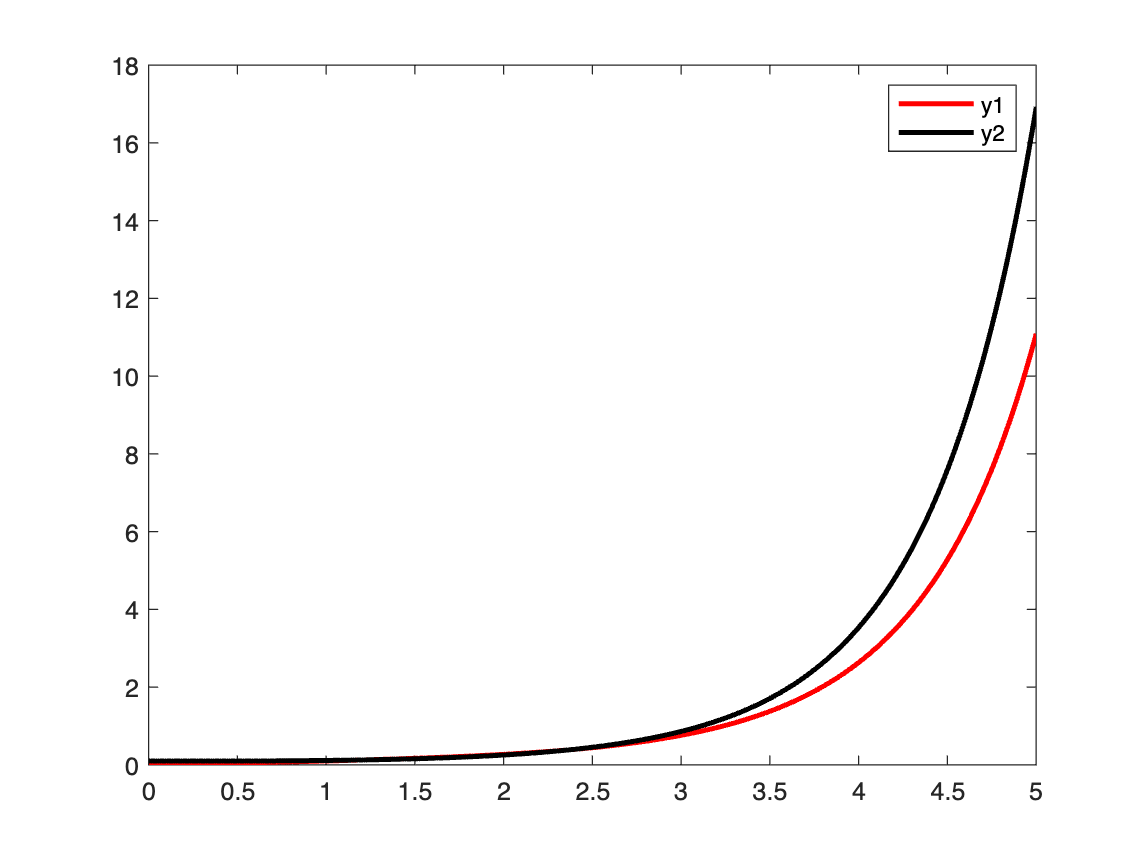

figure
plot(t5,y5(:,1),'-r',t5,y5(:,2),'-k','LineWidth',2)
legend('y1','y2')


% % function dydt = higherode(t,y)
% %     dydt = zeros(2,1);
% %     dydt(1) = y(2);
% %     dydt(2) = 0.5*t*y(1);
% % end



%%%%% solve a secondary ODE. y'' - y' + 3y = t; 
%%%%% y1 = y; y2 = y1'; y2' = y''.
%%%%% y(0) = 1; y'(0) = -2;

[t6,y6] = ode45(@secODE,tspan,[1 -2])

t6 =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


y6 =     1.0000   -2.0000
    0.9798   -2.0499
    0.9590   -2.0996
    0.9378   -2.1490
    0.9160   -2.1982
    0.8938   -2.2471
    0.8711   -2.2958
    0.8479   -2.3441
    0.8242   -2.3921
    0.8000   -2.4398


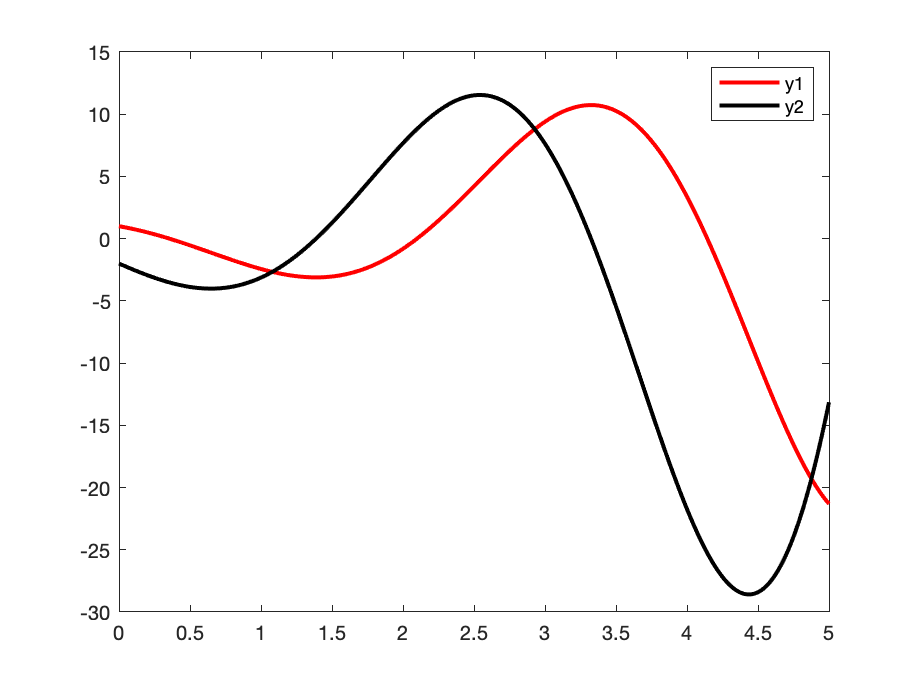

figure
plot(t6,y6(:,1),'-r',t6,y6(:,2),'-k','LineWidth',2)
legend('y1','y2')


% % function dy = secODE(t,y)
% %     dy = zeros(2,1)
% %     dy(1) = y(2);
% %     dy(2) = t + y(2) - 3*y(1)
% % end




%%%%% In-class exercise solve for y''' = y'' + 3y' + 4y + 5. all initial =
%%%%% 0.
[t7,y7] = ode45(@thirdode,tspan,[0 0 0])

t7 =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


y7 =          0         0         0
    0.0000    0.0003    0.0502
    0.0000    0.0010    0.1010
    0.0000    0.0023    0.1522
    0.0001    0.0041    0.2039
    0.0001    0.0064    0.2560
    0.0002    0.0092    0.3086
    0.0003    0.0125    0.3616
    0.0004    0.0164    0.4151
    0.0006    0.0208    0.4689


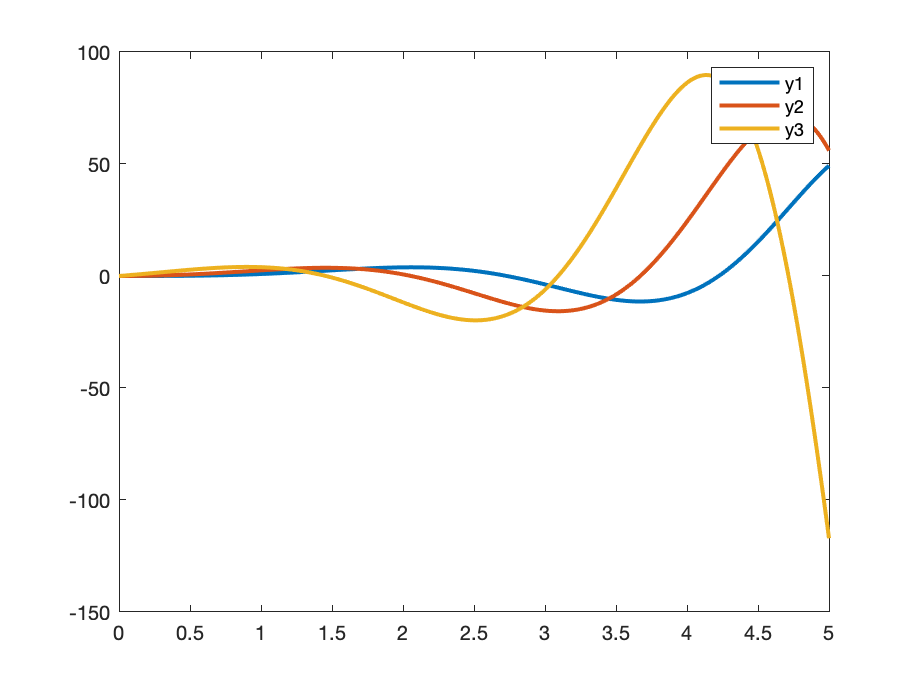

figure
for i = 1:3
    plot(t7,y7(:,i),'LineWidth',2)
    hold on
end
hold off
legend('y1','y2','y3')

function dy = secODE(t,y)
    dy = zeros(2,1);
    dy(1) = y(2);
    dy(2) = t + y(2) - 3*y(1);
end

function dy = thirdode(t,y)
            dy = zeros(3,1);
            dy(1) = y(2);
            dy(2) = y(3);
            dy(3) = y(3) - 3*y(2) - 4*y(1) + 5;
end

function dydt = higherode(t,y)
    dydt = zeros(2,1);
    dydt(1) = y(2);
    dydt(2) = 0.5*t*y(1);
end


function dydt = odesys(t,y,a,b)
    dydt = zeros(2,1);  %%%% because there are two equations
    dydt(1) = y(1)+a*y(2);
    dydt(2) = b*y(1)+a*y(2);
end


function dydt = firstOED(t,y)
    dydt = 2*t;
end

function dydt = secondOED(t,y,a,b)
    dydt = a + b*t;
end

function [y, time] = Eulery(y_old,h,t,t_end)
    y = zeros(t_end,1);
    time = zeros(t_end,1);  
    for i = 1:t_end
        y_new = y_old + h*getEulerf(y_old,t);
        t = t+h;
        y_old = y_new;
        y(i) = y_new;
        time(i) = t;
    end
end


function f = getEulerf(y,t)
    f = 2 - 2*y - exp(-4*t);
end

function [x,f] = getroot(x,tolerance)


f = getf(x);
iter = 0;
iterM = 20;

while abs(f) > tolerance || iter < iterM
    df = getdf(x);
    x = x - f/df;
    f = getf(x);
    iter = iter+1;
end

end


function f = getf(x)
    f = x^2 - 3*x + 2;
end

function df = getdf(x)
    df = 2*x - 3;
end

function y = myIntegrand(x)
    y = sin(x).^3;
end

function y2 = myIntegrand2(x,b)
    y2 = b*cos(x).^2 + sin(x).^3;
end


function pol = poly(x,y,a,b,c)
    pol = x.^2*a + y.^2*b + c;
end

function [m,s] = stat(x)
    n = length(x);
    m = sum(x)/n;
    s = sqrt(sum((x-m).^2/n));
end

function ave = myAve(x)
    ave = sum(x)/length(x); %%% numel(x)
end


